### National

clear all
close all
% General Figure Parameters and Z-Score for 95% confidence intervals
z = 1.96; %z-score
ms = 6;
fs = 16;
fs2 = 12;
lw = 2;

%Defining Actual amounts and x values for plotting
prop = 1;
propactual = 3;
threat = 2;
threatactual = 2;
injury = 3;
injuryactual = 1;

% Finding confidence intervals for Property Encounters
% Belived
meanpropbel_nat = 3.25;
pbSE_nat = 0.03;
HigherCIpb_nat = meanpropbel_nat + z*pbSE_nat;
LowerCIpb_nat = meanpropbel_nat - z*pbSE_nat;
% Desired
meanpropdes_nat = 3.80;
pdSE_nat = 0.03;
HigherCIpd_nat = meanpropdes_nat + z*pdSE_nat;
LowerCIpd_nat = meanpropdes_nat - z*pdSE_nat;

% Finding confidence intervals for Threat Encounters
% Belived
meanthreatbel_nat = 2.96;
tbSE_nat = 0.04;
HigherCItb_nat = meanthreatbel_nat + z*tbSE_nat;
LowerCItb_nat = meanthreatbel_nat - z*tbSE_nat;
% Desired
meanthreatdes_nat = 3.14;
tdSE_nat = 0.03;
HigherCItd_nat = meanthreatdes_nat + z*tdSE_nat;
LowerCItd_nat = meanthreatdes_nat - z*tdSE_nat;

% Finding confidence intervals for Injury Encounters
% Belived
meaninjurybel_nat = 2.65;
ibSE_nat = 0.04;
HigherCIib = meaninjurybel_nat + z*ibSE_nat;
LowerCIib = meaninjurybel_nat - z*ibSE_nat;
% Desired
meaninjurydes_nat = 2.56;
idSE_nat = 0.04;
HigherCIid = meaninjurydes_nat + z*idSE_nat;
LowerCIid = meaninjurydes_nat - z*idSE_nat;

% Plotting
figure(1)
hold on
    fontname("Helvetica")
    
    % Axis Bounds
    xmin = 0.5;
    xmax = 3.5;
    ymin = 0.75;
    ymax = 4.25;
    axis([xmin xmax ymin ymax])

    % Plotting mean points
    bel = plot(prop, meanpropbel_nat, 'o','MarkerSize',ms,'MarkerFaceColor','#1a80bb','MarkerEdgeColor','#1a80bb', 'DisplayName','Believed')

bel =   Line (Believed) with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: [0.1020 0.5020 0.7333]
              XData: 1
              YData: 3.2500

  Show all properties


    
    des = plot(prop, meanpropdes_nat, 'o','MarkerSize',ms,'MarkerFaceColor','#a00000','MarkerEdgeColor','#a00000', 'DisplayName','Preferred')

des =   Line (Preferred) with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: [0.6275 0 0]
              XData: 1
              YData: 3.8000

  Show all properties


    
    plot(threat, meanthreatbel_nat, 'o','MarkerSize',ms,'MarkerFaceColor','#1a80bb','MarkerEdgeColor','#1a80bb')
    
    plot(threat, meanthreatdes_nat, 'o','MarkerSize',ms,'MarkerFaceColor','#a00000','MarkerEdgeColor','#a00000')

    plot(injury, meaninjurybel_nat, 'o','MarkerSize',ms,'MarkerFaceColor','#1a80bb','MarkerEdgeColor','#1a80bb')

    plot(injury, meaninjurydes_nat, 'o','MarkerSize',ms,'MarkerFaceColor','#a00000','MarkerEdgeColor','#a00000')


    % Plotting actual points
    act = plot(prop, propactual, 'o','MarkerSize',ms,'MarkerFaceColor','k','MarkerEdgeColor','k', 'DisplayName','Guideline')

act =   Line (Guideline) with properties:

              Color: [0.6350 0.0780 0.1840]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: [0 0 0]
              XData: 1
              YData: 3

  Show all properties


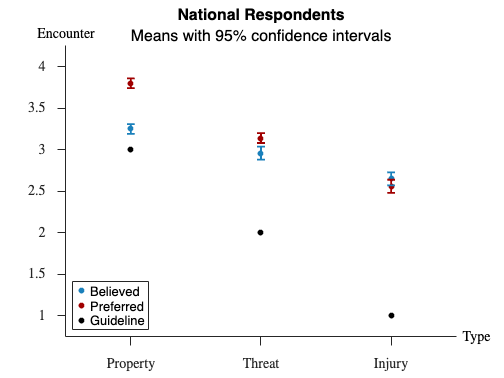


    plot(threat, threatactual, 'o','MarkerSize',ms,'MarkerFaceColor','k','MarkerEdgeColor','k')

    plot(injury, injuryactual, 'o','MarkerSize',ms,'MarkerFaceColor','k','MarkerEdgeColor','k')


    % Plotting Vertical Confidence Interval Lines
    plot([prop prop], [LowerCIpb_nat HigherCIpb_nat], '-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([prop prop], [LowerCIpd_nat HigherCIpd_nat], '-', 'LineWidth', lw, 'Color', '#a00000')

    plot([threat threat], [LowerCItb_nat HigherCItb_nat], '-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([threat threat], [LowerCItd_nat HigherCItd_nat], '-', 'LineWidth', lw, 'Color', '#a00000')

    plot([injury injury], [LowerCIib HigherCIib], '-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([injury injury], [LowerCIid HigherCIid], '-', 'LineWidth', lw, 'Color', '#a00000')

    % Plotting Horizontal hat and feet for CI
    plot([0.97*prop 1.03*prop],[LowerCIpb_nat LowerCIpb_nat],'-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([0.97*prop 1.03*prop],[HigherCIpb_nat HigherCIpb_nat],'-', 'LineWidth', lw, 'Color', '#1a80bb')

    plot([0.97*prop 1.03*prop],[LowerCIpd_nat LowerCIpd_nat],'-', 'LineWidth', lw, 'Color', '#a00000')
    plot([0.97*prop 1.03*prop],[HigherCIpd_nat HigherCIpd_nat],'-', 'LineWidth', lw, 'Color', '#a00000')

    plot([0.97*prop+1 1.03*prop+1],[LowerCItb_nat LowerCItb_nat],'-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([0.97*prop+1 1.03*prop+1],[HigherCItb_nat HigherCItb_nat],'-', 'LineWidth', lw, 'Color', '#1a80bb')

    plot([0.97*prop+1 1.03*prop+1],[LowerCItd_nat LowerCItd_nat],'-', 'LineWidth', lw, 'Color', '#a00000')
    plot([0.97*prop+1 1.03*prop+1],[HigherCItd_nat HigherCItd_nat],'-', 'LineWidth', lw, 'Color', '#a00000')

    plot([0.97*prop+2 1.03*prop+2],[LowerCIib LowerCIib],'-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([0.97*prop+2 1.03*prop+2],[HigherCIib HigherCIib],'-', 'LineWidth', lw, 'Color', '#1a80bb')

    plot([0.97*prop+2 1.03*prop+2],[LowerCIid LowerCIid],'-', 'LineWidth', lw, 'Color', '#a00000')
    plot([0.97*prop+2 1.03*prop+2],[HigherCIid HigherCIid],'-', 'LineWidth', lw, 'Color', '#a00000')

    % Nudgets
    xe = 0.01*xmax;
    ye = 0.01*ymax;

    % Axis Labels
    xl = xmax + xe;
    yl = ymax + ye;

    % Axis Label actual words
        text(xl,ymin,'Type' , ...
            'HorizontalAlignment','left','VerticalAlignment','middle', ...
            'FontSize',16,'Interpreter','latex');
        text(xmin, yl, 'Encounter', ...
            'HorizontalAlignment','center','VerticalAlignment','bottom', ...
            'FontSize',16,'Interpreter','latex');

    % Title
    title('National Respondents')
    subtitle('Means with 95% confidence intervals')
    % Axis Ticks
    xticks([prop threat injury])
    xticklabels({'Property', 'Threat', 'Injury'})

    yticks([1 1.5 2 2.5 3 3.5 4])
    set(gca,'TickLabelInterpreter','latex','TickDir','out','FontSize',fs)
    legend([bel des act],'Location','southwest')

    print('resultsNational','-depsc');
hold off

### Regional

% General Figure Parameters and Z-Score for 95% confidence intervals
z = 1.96; %z-score
ms = 8;
fs = 16;
fs2 = 12;
lw = 2;

%Defining Actual amounts and x values for plotting
prop = 1;
propactual = 3;
threat = 2;
threatactual = 2;
injury = 3;
injuryactual = 1;

% Finding confidence intervals for Property Encounters
% Belived
meanpropbel_reg = 3.25;
pbSE_reg = 0.03;
HigherCIpb_reg = meanpropbel_reg + z*pbSE_reg;
LowerCIpb_reg = meanpropbel_reg - z*pbSE_reg;
% Desired
meanpropdes_reg = 3.80;
pdSE_reg = 0.03;
HigherCIpd_reg = meanpropdes_reg + z*pdSE_reg;
LowerCIpd_reg = meanpropdes_reg - z*pdSE_reg;

% Finding confidence intervals for Threat Encounters
% Belived
meanthreatbel_reg = 2.96;
tbSE_reg = 0.04;
HigherCItb_reg = meanthreatbel_reg + z*tbSE_reg;
LowerCItb_reg = meanthreatbel_reg - z*tbSE_reg;
% Desired
meanthreatdes_reg = 3.14;
tdSE_reg = 0.03;
HigherCItd_reg = meanthreatdes_reg + z*tdSE_reg;
LowerCItd_reg = meanthreatdes_reg - z*tdSE_reg;

% Finding confidence intervals for Injury Encounters
% Belived
meaninjurybel_reg = 2.65;
ibSE_reg = 0.04;
HigherCIib = meaninjurybel_reg + z*ibSE_reg;
LowerCIib = meaninjurybel_reg - z*ibSE_reg;
% Desired
meaninjurydes_reg = 2.56;
idSE_reg = 0.04;
HigherCIid = meaninjurydes_reg + z*idSE_reg;
LowerCIid = meaninjurydes_reg - z*idSE_reg;

% Plotting
figure(2)
hold on
    fontname("Helvetica")

    % Axis Bounds
    xmin = 0.5;
    xmax = 3.5;
    ymin = 0.75;
    ymax = 4.25;
    axis([xmin xmax ymin ymax])

    % Plotting mean points
    bel = plot(prop, meanpropbel_reg, 'o','MarkerSize',ms,'MarkerFaceColor','#1a80bb','MarkerEdgeColor','#1a80bb', 'DisplayName','Believed')

bel =   Line (Believed) with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 8
    MarkerFaceColor: [0.1020 0.5020 0.7333]
              XData: 1
              YData: 3.2500

  Show all properties



    des = plot(prop, meanpropdes_reg, 'o','MarkerSize',ms,'MarkerFaceColor','#a00000','MarkerEdgeColor','#a00000', 'DisplayName', 'Preferred')

des =   Line (Preferred) with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 8
    MarkerFaceColor: [0.6275 0 0]
              XData: 1
              YData: 3.8000

  Show all properties



    plot(threat, meanthreatbel_reg, 'o','MarkerSize',ms,'MarkerFaceColor','#1a80bb','MarkerEdgeColor','#1a80bb')

    plot(threat, meanthreatdes_reg, 'o','MarkerSize',ms,'MarkerFaceColor','#a00000','MarkerEdgeColor','#a00000')

    plot(injury, meaninjurybel_reg, 'o','MarkerSize',ms,'MarkerFaceColor','#1a80bb','MarkerEdgeColor','#1a80bb')

    plot(injury, meaninjurydes_reg, 'o','MarkerSize',ms,'MarkerFaceColor','#a00000','MarkerEdgeColor','#a00000')

    % Plotting actual points
    act = plot(prop, propactual, 'o','MarkerSize',ms,'MarkerFaceColor','k','MarkerEdgeColor','k', 'DisplayName', 'Guideline')

act =   Line (Guideline) with properties:

              Color: [0.6350 0.0780 0.1840]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 8
    MarkerFaceColor: [0 0 0]
              XData: 1
              YData: 3

  Show all properties


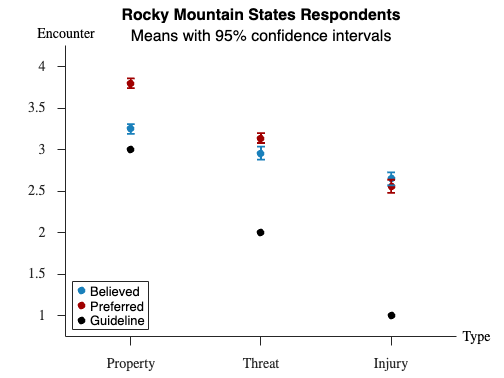


    plot(threat, threatactual, 'o','MarkerSize',ms,'MarkerFaceColor','k','MarkerEdgeColor','k')

    plot(injury, injuryactual, 'o','MarkerSize',ms,'MarkerFaceColor','k','MarkerEdgeColor','k')

    % Plotting Vertical Confidence Interval Lines
    plot([prop prop], [LowerCIpb_reg HigherCIpb_reg], '-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([prop prop], [LowerCIpd_reg HigherCIpd_reg], '-', 'LineWidth', lw, 'Color', '#a00000')

    plot([threat threat], [LowerCItb_reg HigherCItb_reg], '-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([threat threat], [LowerCItd_reg HigherCItd_reg], '-', 'LineWidth', lw, 'Color', '#a00000')

    plot([injury injury], [LowerCIib HigherCIib], '-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([injury injury], [LowerCIid HigherCIid], '-', 'LineWidth', lw, 'Color', '#a00000')

    % Plotting Horizontal hat and feet for CI
    plot([0.97*prop 1.03*prop],[LowerCIpb_reg LowerCIpb_reg],'-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([0.97*prop 1.03*prop],[HigherCIpb_reg HigherCIpb_reg],'-', 'LineWidth', lw, 'Color', '#1a80bb')

    plot([0.97*prop 1.03*prop],[LowerCIpd_reg LowerCIpd_reg],'-', 'LineWidth', lw, 'Color', '#a00000')
    plot([0.97*prop 1.03*prop],[HigherCIpd_reg HigherCIpd_reg],'-', 'LineWidth', lw, 'Color', '#a00000')

    plot([0.97*prop+1 1.03*prop+1],[LowerCItb_reg LowerCItb_reg],'-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([0.97*prop+1 1.03*prop+1],[HigherCItb_reg HigherCItb_reg],'-', 'LineWidth', lw, 'Color', '#1a80bb')

    plot([0.97*prop+1 1.03*prop+1],[LowerCItd_reg LowerCItd_reg],'-', 'LineWidth', lw, 'Color', '#a00000')
    plot([0.97*prop+1 1.03*prop+1],[HigherCItd_reg HigherCItd_reg],'-', 'LineWidth', lw, 'Color', '#a00000')

    plot([0.97*prop+2 1.03*prop+2],[LowerCIib LowerCIib],'-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([0.97*prop+2 1.03*prop+2],[HigherCIib HigherCIib],'-', 'LineWidth', lw, 'Color', '#1a80bb')

    plot([0.97*prop+2 1.03*prop+2],[LowerCIid LowerCIid],'-', 'LineWidth', lw, 'Color', '#a00000')
    plot([0.97*prop+2 1.03*prop+2],[HigherCIid HigherCIid],'-', 'LineWidth', lw, 'Color', '#a00000')

    % Nudgets
    xe = 0.01*xmax;
    ye = 0.01*ymax;

    % Axis Labels
    xl = xmax + xe;
    yl = ymax + ye;

    % Axis Label actual words
        text(xl,ymin,'Type' , ...
            'HorizontalAlignment','left','VerticalAlignment','middle', ...
            'FontSize',16,'Interpreter','latex');
        text(xmin, yl, 'Encounter', ...
            'HorizontalAlignment','center','VerticalAlignment','bottom', ...
            'FontSize',16,'Interpreter','latex');

    % Title
    title('Rocky Mountain States Respondents')
    subtitle('Means with 95% confidence intervals')
    % Axis Ticks
    xticks([prop threat injury])
    xticklabels({'Property', 'Threat', 'Injury'})

    yticks([1 1.5 2 2.5 3 3.5 4])
    set(gca,'TickLabelInterpreter','latex','TickDir','out','FontSize',fs)

    legend([bel des act],'Location','southwest')

    print('resultsRegional','-depsc');
hold off

% General Figure Parameters and Z-Score for 95% confidence intervals
clear all
z = 1.96; %z-score
ms = 8;
fs = 16;
fs2 = 12;
lw = 2;

%Defining Actual amounts and x values for plotting
prop = 1;
propactual = 3;
threat = 2;
threatactual = 2;
injury = 3;
injuryactual = 1;
nudge = 0.1;

% In Region Believed
meanpropbel_in = 3.39;
propbel_in_ci_h = 3.78;
propbel_in_ci_l = 3;

meanthreatbel_in = 3.03;
threatbel_in_ci_h = 3.47;
threatbel_in_ci_l = 2.58;

meaninjbel_in = 2.76;
injbel_in_ci_h = 3.31;
injbel_in_ci_l = 2.22;

% In Region Desired
meanpropdes_in = 3.84;
propdes_in_ci_h = 4.27;
propdes_in_ci_l = 3.41;

meanthreatdes_in = 3.11;
threatdes_in_ci_h = 3.59;
threatdes_in_ci_l = 2.62;

meaninjdes_in = 2.61;
injdes_in_ci_h = 3.12;
injdes_in_ci_l = 2.1;

% Out of Region Believed
meanpropbel_out = 3.35;
propbel_out_ci_h = 3.5;
propbel_out_ci_l = 3.19;

meanthreatbel_out = 2.87;
threatbel_out_ci_h = 3;
threatbel_out_ci_l = 2.73;

meaninjbel_out = 2.48;
injbel_out_ci_h = 2.67;
injbel_out_ci_l = 2.29;

% In Region Desired
meanpropdes_out = 3.86;
propdes_out_ci_h = 4.02;
propdes_out_ci_l = 3.71;

meanthreatdes_out = 3.12;
threatdes_out_ci_h = 3.27;
threatdes_out_ci_l = 2.96;

meaninjdes_out = 2.53;
injdes_out_ci_h = 2.71;
injdes_out_ci_l = 2.34;

% Plotting
figure(3)
hold on
    fontname("Helvetica")

    % Axis Bounds
    xmin = 0.5;
    xmax = 3.5;
    ymin = 0.75;
    ymax = 4.3;
    axis([xmin xmax ymin ymax])

    % Plotting mean points
    bel = plot(prop-nudge, meanpropbel_in, 'o','MarkerSize',ms,'MarkerFaceColor','#1a80bb','MarkerEdgeColor','#1a80bb', 'DisplayName','Believed, In Habitat')

bel =   Line (Believed, In Habitat) with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 8
    MarkerFaceColor: [0.1020 0.5020 0.7333]
              XData: 0.9000
              YData: 3.3900

  Show all properties



    des = plot(prop-nudge, meanpropdes_in, 'o','MarkerSize',ms,'MarkerFaceColor','#a00000','MarkerEdgeColor','#a00000', 'DisplayName', 'Preferred, In Habitat')

des =   Line (Preferred, In Habitat) with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 8
    MarkerFaceColor: [0.6275 0 0]
              XData: 0.9000
              YData: 3.8400

  Show all properties



    bel1 = plot(prop+nudge, meanpropbel_out, 'o','MarkerSize',ms,'MarkerFaceColor','none','MarkerEdgeColor','#1a80bb', 'DisplayName','Believed, Out of Habitat')

bel1 =   Line (Believed, Out of Habitat) with properties:

              Color: [0.9290 0.6940 0.1250]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 8
    MarkerFaceColor: 'none'
              XData: 1.1000
              YData: 3.3500

  Show all properties



    des1 = plot(prop+nudge, meanpropdes_out, 'o','MarkerSize',ms,'MarkerFaceColor','none','MarkerEdgeColor','#a00000', 'DisplayName','Preferred, Out of Habitat')

des1 =   Line (Preferred, Out of Habitat) with properties:

              Color: [0.4940 0.1840 0.5560]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 8
    MarkerFaceColor: 'none'
              XData: 1.1000
              YData: 3.8600

  Show all properties



    plot(threat-nudge, meanthreatbel_in, 'o','MarkerSize',ms,'MarkerFaceColor','#1a80bb','MarkerEdgeColor','#1a80bb')

    plot(threat-nudge, meanthreatdes_in, 'o','MarkerSize',ms,'MarkerFaceColor','#a00000','MarkerEdgeColor','#a00000')

    plot(threat+nudge, meanthreatbel_out, 'o','MarkerSize',ms,'MarkerFaceColor','none','MarkerEdgeColor','#1a80bb')

    plot(threat+nudge, meanthreatdes_out, 'o','MarkerSize',ms,'MarkerFaceColor','none','MarkerEdgeColor','#a00000')
    
    plot(injury-nudge, meaninjbel_in, 'o','MarkerSize',ms,'MarkerFaceColor','#1a80bb','MarkerEdgeColor','#1a80bb')

    plot(injury-nudge, meaninjdes_in, 'o','MarkerSize',ms,'MarkerFaceColor','#a00000','MarkerEdgeColor','#a00000')

    plot(injury+nudge, meaninjbel_out, 'o','MarkerSize',ms,'MarkerFaceColor','none','MarkerEdgeColor','#1a80bb')

    plot(injury+nudge, meaninjdes_out, 'o','MarkerSize',ms,'MarkerFaceColor','none','MarkerEdgeColor','#a00000')

    % Plotting actual points
    act = plot(prop, propactual, 'o','MarkerSize',ms,'MarkerFaceColor','k','MarkerEdgeColor','k', 'DisplayName', 'Guideline')

act =   Line (Guideline) with properties:

              Color: [0.3010 0.7450 0.9330]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 8
    MarkerFaceColor: [0 0 0]
              XData: 1
              YData: 3

  Show all properties


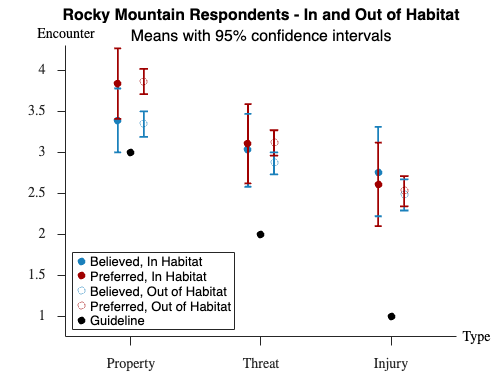


    plot(threat, threatactual, 'o','MarkerSize',ms,'MarkerFaceColor','k','MarkerEdgeColor','k')

    plot(injury, injuryactual, 'o','MarkerSize',ms,'MarkerFaceColor','k','MarkerEdgeColor','k')

    % Plotting Vertical Confidence Interval Line
    plot([prop-nudge prop-nudge], [propbel_in_ci_l propbel_in_ci_h], '-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([prop-nudge prop-nudge], [propdes_in_ci_l propdes_in_ci_h], '-', 'LineWidth', lw, 'Color', '#a00000')

    plot([prop+nudge prop+nudge], [propbel_out_ci_l propbel_out_ci_h], '-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([prop+nudge prop+nudge], [propdes_out_ci_l propdes_out_ci_h], '-', 'LineWidth', lw, 'Color', '#a00000')

    plot([threat-nudge threat-nudge], [threatbel_in_ci_l threatbel_in_ci_h], '-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([threat-nudge threat-nudge], [threatdes_in_ci_l threatdes_in_ci_h], '-', 'LineWidth', lw, 'Color', '#a00000')

    plot([threat+nudge threat+nudge], [threatbel_out_ci_l threatbel_out_ci_h], '-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([threat+nudge threat+nudge], [threatdes_out_ci_l threatdes_out_ci_h], '-', 'LineWidth', lw, 'Color', '#a00000')

    plot([injury-nudge injury-nudge], [injbel_in_ci_l injbel_in_ci_h], '-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([injury-nudge injury-nudge], [injdes_in_ci_l injdes_in_ci_h], '-', 'LineWidth', lw, 'Color', '#a00000')

    plot([injury+nudge injury+nudge], [injbel_out_ci_l injbel_out_ci_h], '-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([injury+nudge injury+nudge], [injdes_out_ci_l injdes_out_ci_h], '-', 'LineWidth', lw, 'Color', '#a00000')


    % Plotting Horizontal hat and feet for CI
    plot([0.97*(prop-nudge) 1.03*(prop-nudge)],[propbel_in_ci_l propbel_in_ci_l],'-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([0.97*(prop-nudge) 1.03*(prop-nudge)],[propbel_in_ci_h propbel_in_ci_h],'-', 'LineWidth', lw, 'Color', '#1a80bb')

    plot([0.97*(prop+nudge) 1.03*(prop+nudge)],[propbel_out_ci_l propbel_out_ci_l],'-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([0.97*(prop+nudge) 1.03*(prop+nudge)],[propbel_out_ci_h propbel_out_ci_h],'-', 'LineWidth', lw, 'Color', '#1a80bb')

    plot([0.97*(prop-nudge) 1.03*(prop-nudge)],[propdes_in_ci_l propdes_in_ci_l],'-', 'LineWidth', lw, 'Color', '#a00000')
    plot([0.97*(prop-nudge) 1.03*(prop-nudge)],[propdes_in_ci_h propdes_in_ci_h],'-', 'LineWidth', lw, 'Color', '#a00000')

    plot([0.97*(prop+nudge) 1.03*(prop+nudge)],[propdes_out_ci_l propdes_out_ci_l],'-', 'LineWidth', lw, 'Color', '#a00000')
    plot([0.97*(prop+nudge) 1.03*(prop+nudge)],[propdes_out_ci_h propdes_out_ci_h],'-', 'LineWidth', lw, 'Color', '#a00000')

    plot([0.97*(prop-nudge)+1 1.03*(prop-nudge)+1],[threatbel_in_ci_l threatbel_in_ci_l],'-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([0.97*(prop-nudge)+1 1.03*(prop-nudge)+1],[threatbel_in_ci_h threatbel_in_ci_h],'-', 'LineWidth', lw, 'Color', '#1a80bb')

    plot([0.97*(prop+nudge)+1 1.03*(prop+nudge)+1],[threatbel_out_ci_l threatbel_out_ci_l],'-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([0.97*(prop+nudge)+1 1.03*(prop+nudge)+1],[threatbel_out_ci_h threatbel_out_ci_h],'-', 'LineWidth', lw, 'Color', '#1a80bb')

    plot([0.97*(prop-nudge)+1 1.03*(prop-nudge)+1],[threatdes_in_ci_l threatdes_in_ci_l],'-', 'LineWidth', lw, 'Color', '#a00000')
    plot([0.97*(prop-nudge)+1 1.03*(prop-nudge)+1],[threatdes_in_ci_h threatdes_in_ci_h],'-', 'LineWidth', lw, 'Color', '#a00000')

    plot([0.97*(prop+nudge)+1 1.03*(prop+nudge)+1],[threatdes_out_ci_l threatdes_out_ci_l],'-', 'LineWidth', lw, 'Color', '#a00000')
    plot([0.97*(prop+nudge)+1 1.03*(prop+nudge)+1],[threatdes_out_ci_h threatdes_out_ci_h],'-', 'LineWidth', lw, 'Color', '#a00000')

    plot([0.97*(prop-nudge)+2 1.03*(prop-nudge)+2],[injbel_in_ci_l injbel_in_ci_l],'-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([0.97*(prop-nudge)+2 1.03*(prop-nudge)+2],[injbel_in_ci_h injbel_in_ci_h],'-', 'LineWidth', lw, 'Color', '#1a80bb')

    plot([0.97*(prop+nudge)+2 1.03*(prop+nudge)+2],[injbel_out_ci_l injbel_out_ci_l],'-', 'LineWidth', lw, 'Color', '#1a80bb')
    plot([0.97*(prop+nudge)+2 1.03*(prop+nudge)+2],[injbel_out_ci_h injbel_out_ci_h],'-', 'LineWidth', lw, 'Color', '#1a80bb')

    plot([0.97*(prop-nudge)+2 1.03*(prop-nudge)+2],[injdes_in_ci_l injdes_in_ci_l],'-', 'LineWidth', lw, 'Color', '#a00000')
    plot([0.97*(prop-nudge)+2 1.03*(prop-nudge)+2],[injdes_in_ci_h injdes_in_ci_h],'-', 'LineWidth', lw, 'Color', '#a00000')

    plot([0.97*(prop+nudge)+2 1.03*(prop+nudge)+2],[injdes_out_ci_l injdes_out_ci_l],'-', 'LineWidth', lw, 'Color', '#a00000')
    plot([0.97*(prop+nudge)+2 1.03*(prop+nudge)+2],[injdes_out_ci_h injdes_out_ci_h],'-', 'LineWidth', lw, 'Color', '#a00000')

    % Nudgets
    xe = 0.01*xmax;
    ye = 0.01*ymax;

    % Axis Labels
    xl = xmax + xe;
    yl = ymax + ye;

    % Axis Label actual words
        text(xl,ymin,'Type' , ...
            'HorizontalAlignment','left','VerticalAlignment','middle', ...
            'FontSize',16,'Interpreter','latex');
        text(xmin, yl, 'Encounter', ...
            'HorizontalAlignment','center','VerticalAlignment','bottom', ...
            'FontSize',16,'Interpreter','latex');

    % Title
    title('Rocky Mountain Respondents - In and Out of Habitat')
    subtitle('Means with 95% confidence intervals')
    % Axis Ticks
    xticks([prop threat injury])
    xticklabels({'Property', 'Threat', 'Injury'})

    yticks([1 1.5 2 2.5 3 3.5 4])
    set(gca,'TickLabelInterpreter','latex','TickDir','out','FontSize',fs)

    legend([bel des bel1 des1 act], 'Location','southwest')

    print('resultsSubRegional','-depsc');
hold off